# Uterus

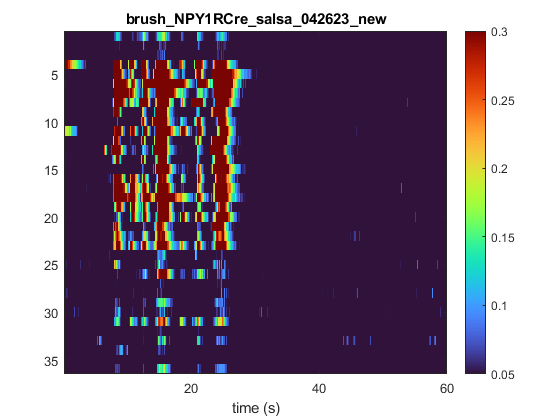

figure, imagesc(normDeltaF(1:end,:)'),colormap(turbo),
% axis off
colorbar
% set(gcf,'Visible','on')
% play with the x axis ticks and labels
if size(normDeltaF,1) <3000
    interval = 200; 
else
    interval = ceil(size(normDeltaF,1)/800)*100; 
end
xticks(interval:interval:size(normDeltaF,1));
timelabel = strsplit(num2str(interval/fps:interval/fps:size(normDeltaF,1)/fps));
xticklabels(timelabel); xlabel("time (s)")
% play with the colorbar scale
Max = sort(max(normDeltaF)); 
if size(normDeltaF,2)>4
    MaxLimit = mean(Max(end-4:end));
else
    MaxLimit = max(Max);
end

if MaxLimit > 1.5 || MaxLimit < 0.2
    Limit = 1.5;
else
    Limit = MaxLimit;
end

% Limit = 1.5;
caxis([0.05 0.3])
pathparts = strsplit(path,filesep);
mouseID = pathparts{end-1}; clear pathparts
name = [filename(1:end-4), '_', mouseID,'_new'];
t = title(name);
set(t,'Interpreter','none')

figureName = [path, name, '.jpg'];
saveas(gcf,figureName)

std = 3; 
